## 基本

気象庁の毎時潮位観測資料は，地点ごとおよび月ごとにファイルが分かれています．

このため，観測地点名・年・月を入力してインスタンスを生成し，変数の初期化を行います．

tidegauge = JMAtide('東京', 2019, 10)

tidegauge =   JMAtide のプロパティ:

          station: '東京'
             year: 2019
            month: 10
             time: []
            ndays: []
              ssh: []
             ssha: []
              lon: 139.7667
              lat: 35.6500
          url_ssh: 'https://www.data.jma.go.jp/gmd/kaiyou/data/db/tide/genbo/2019/201910/hry201910TK.txt'
         url_ssha: 'https://www.data.jma.go.jp/gmd/kaiyou/data/db/tide/genbo/2019/201910/dep201910TK.txt'
             unit: 'cm'
    standard_time: 'JST(UTC+9)'


LoadSSH, LoadSSHA でそれぞれ潮位，潮位偏差を気象庁ウェブサイトから取得します．

格納されるプロパティ名は ssh と ssha です．

tidegauge = tidegauge.LoadSSH; % 潮位
tidegauge = tidegauge.LoadSSHA; % 潮位偏差

PlotSSH，PlotSSHA で取得したデータの簡易的なプロットが可能です．

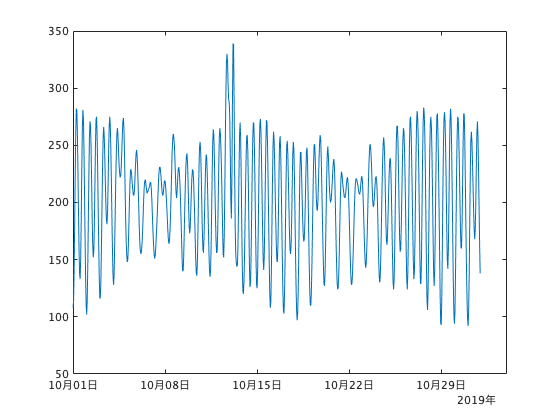

% 潮位のプロット
tidegauge.PlotSSH;

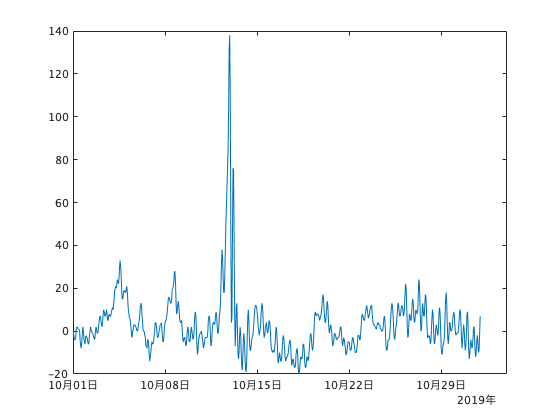

% 潮位偏差のプロット
tidegauge.PlotSSHA;

## 長期（２ヶ月以上）のデータ取得

年月の指定部分に配列を入力することで，長期間の潮位データを対象とすることが可能です．

tidegauge = JMAtide('東京', 2019); % 2019年1月〜12月, (1x12)配列
tidegauge = JMAtide('東京', [2018,09; 2019,10]); % 2018年9月 と 2019年10月, (1x2)配列
tidegauge = JMAtide('東京', 2019, 8:11) % 2019年9月〜11月, (1x4)配列

tidegauge =   1×4 JMAtide 配列のプロパティ:

    station
    year
    month
    time
    ndays
    ssh
    ssha
    lon
    lat
    url_ssh
    url_ssha
    unit
    standard_time


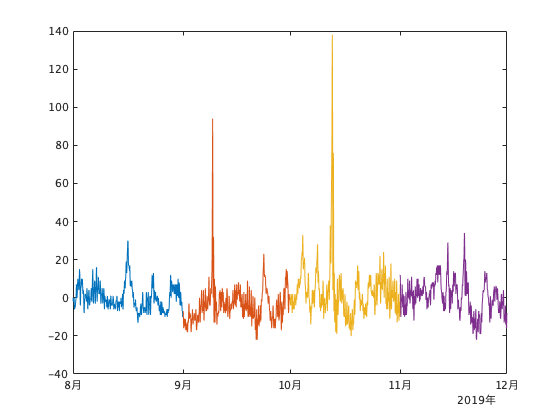

tidegauge = tidegauge.LoadSSHA;
tidegauge.PlotSSHA;

## 複数地点のデータ取得

地点名を cell 配列で複数指定すると，複数地点の潮位データを同時に扱えます．

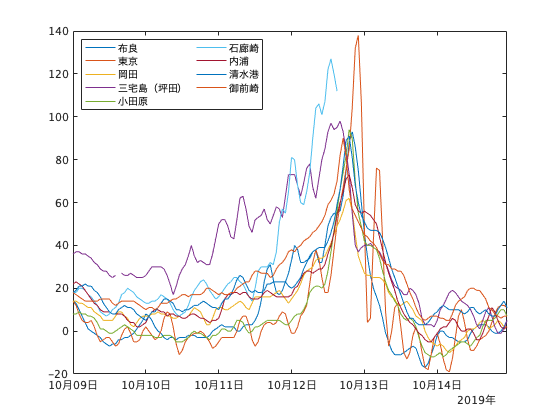

% 以下の9地点，2019年10月
tidegauge = JMAtide({'布良','東京','岡田','三宅島（坪田）','小田原','石廊崎','内浦','清水港','御前崎'}, 2019, 10);

% 潮位取得
tidegauge = tidegauge.LoadSSH;

% 潮位偏差取得
tidegauge = tidegauge.LoadSSHA;

% plot - 潮位偏差
lines = tidegauge.PlotSSHA;
xlim([tidegauge(1).time(24*8)+hours(1), tidegauge(1).time(24*14)])
legend(lines, {'布良','東京','岡田','三宅島（坪田）','小田原','石廊崎','内浦','清水港','御前崎'}, 'NumColumns',2, 'Location','NorthWest');

## CSVファイルへの出力

CSVSSH，CSVSSHAでそれぞれ潮位，潮位偏差を CSV ファイルとして出力します．

データの期間（年，月）が同じであれば，複数の地点を1つのファイルにまとめて出力します．

% ファイル出力前に，単位を cm → m へ
tidegauge = tidegauge.ConvertUnit('m');

% CSVファイルとして出力
% 同一期間のため，全地点のデータを1つのファイルに格納
tidegauge.CSVSSH  % 潮位

sealevel_201910_MRTKOKMJODG9UCSMOM.dat


tidegauge.CSVSSHA % 潮位偏差

sealevelanomaly_201910_MRTKOKMJODG9UCSMOM.dat


% 出力ファイルの確認 1行目〜10行目
dbtype sealevel_201910_MRTKOKMJODG9UCSMOM.dat 1:10

1     # time, 布良, 東京, 岡田, 三宅島（坪田）, 小田原, 石廊崎, 内浦, 清水港, 御前崎
2     20191001T0000,    0.830,    1.080,    0.840,    3.770,    2.760,    3.250,    1.040,    1.320,    1.530
3     20191001T0100,    0.980,    1.130,    0.930,    3.840,    2.870,    3.220,    1.030,    1.260,    1.510
4     20191001T0200,    1.250,    1.390,    1.160,    4.080,    3.120,    3.370,    1.220,    1.370,    1.670
5     20191001T0300,    1.570,    1.790,    1.480,    4.400,    3.450,    3.660,    1.560,    1.610,    1.960
6     20191001T0400,    1.870,    2.230,    1.800,    4.710,    3.770,    4.030,    1.940,    1.950,    2.300
7     20191001T0500,    2.060,    2.600,    2.040,    4.970,    4.000,    4.400,    2.280,    2.300,    2.630
8     20191001T0600,    2.130,    2.820,    2.140,    5.120,    4.100,    4.650,    2.510,    2.570,    2.850
9     20191001T0700,    2.050,    2.810,    2.120,    5.140,    4.060,    4.740,    2.590,    2.700,    2.930
10    20191001T0800,    1.840,    2.610,    1.970,    5.000,  